rng(1); %for reproduciability and to use the same randn function later
        %but with different values for testing

% Creating synthetic input (sine wave)
inputSize = 4;
outputSize = 1;
XTrain = randn(inputSize, 2000);
YTrain = XTrain(1,:).*sin(XTrain(2,:)) + XTrain(3,:).*sin(XTrain(4,:));

% Create LSTM network with 25 hidden units
numHiddenUnits = 25;

layers = [
    sequenceInputLayer(inputSize) 
    lstmLayer(numHiddenUnits) 
    fullyConnectedLayer(outputSize) 
    regressionLayer];

% Define training options
options = trainingOptions('adam', ...
    'MaxEpochs', 500, ...
    'MiniBatchSize', 64, ...
    'GradientThreshold', 1, ...
    'InitialLearnRate', 0.05, ...
    'Verbose', false);

% Train LSTM network
net = trainNetwork(XTrain,YTrain,layers,options);

% testing with random values
rng(2);

XTest = randn(inputSize, 2000);
YTest = XTest(1,:).*sin(XTest(2,:)) + XTest(3,:).*sin(XTest(4,:));

YPredicted = predict(net, XTest)

YPredicted = 1×2000 single row vector
    0.1258    0.1122    0.5532   -0.9711   -0.5116   -0.0908    0.2300    0.3312   -0.1903   -0.0678   -0.8798   -0.3063    0.0570   -0.2994    2.9750    0.2625    0.5002   -0.3212    0.5057    0.0786   -0.6863   -0.1096   -0.1179    1.3615   -0.6807    0.1155   -0.4314   -0.8314   -0.0437   -0.4889    1.0800    1.4361    2.1558    0.6316    0.6607   -1.3800   -0.8183    0.0896    1.1736   -0.0220   -0.8145    0.3582    0.0758    0.0575   -0.7149   -0.5032   -2.1946   -0.3050    0.0432   -0.1304



rmse = sqrt(mean((YTest - YPredicted).^2))

rmse = single
0.2067

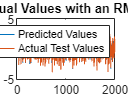

plot(YPredicted);
hold on;
plot(YTest);
hold off;
legend('Predicted Values', 'Actual Test Values')
title("Predicted vs Actual Values with an RMS error of " + rmse);